clc,clear

## Main

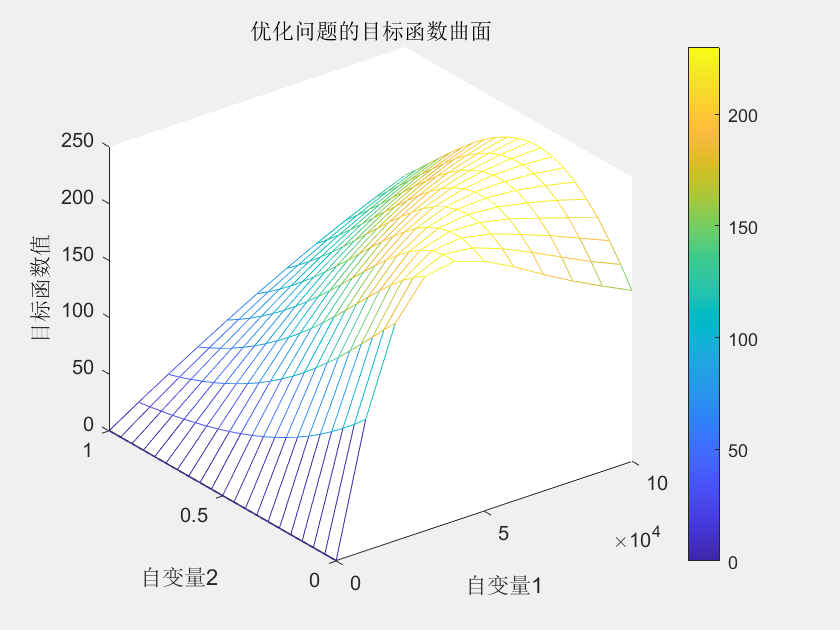

x1_range = 0:10000:100000;  % 自变量1的范围：0到100000
x2_range = 0:0.05:1;  % 自变量2的范围：0到1

% 计算目标函数值
[X1, X2] = meshgrid(x1_range, x2_range);
Z = zeros(size(X1));
for i = 1:numel(X1)
    Z(i) = -Obj_fun([X1(i), X2(i)]);
end

% 绘制三维曲面
mesh(X1, X2, Z);
colormap("parula");
colorbar;
% 启用交互式旋转
rotate3d on;
% 添加标题和轴标签
title('优化问题的目标函数曲面');
xlabel('自变量1');
ylabel('自变量2');
zlabel('目标函数值');


                                 Best            Mean     Stall
Iteration     f-count            f(x)            f(x)    Iterations
    0              20          -229.1          -156.2        0
    1              40          -229.2          -156.7        0
    2              60          -229.3          -195.5        0
    3              80          -229.4          -167.5        0
    4             100          -229.5          -193.2        0
    5             120          -229.5          -210.4        1
    6             140          -229.9            -200        0
    7             160          -229.9          -184.1        1
    8             180          -229.9          -187.7        2
    9             200          -229.9          -189.6        3
   10             220          -229.9          -182.9        4
   11             240          -229.9          -188.5        5
   12             260          -230.1          -185.7        0
   13             280          -230.1          -

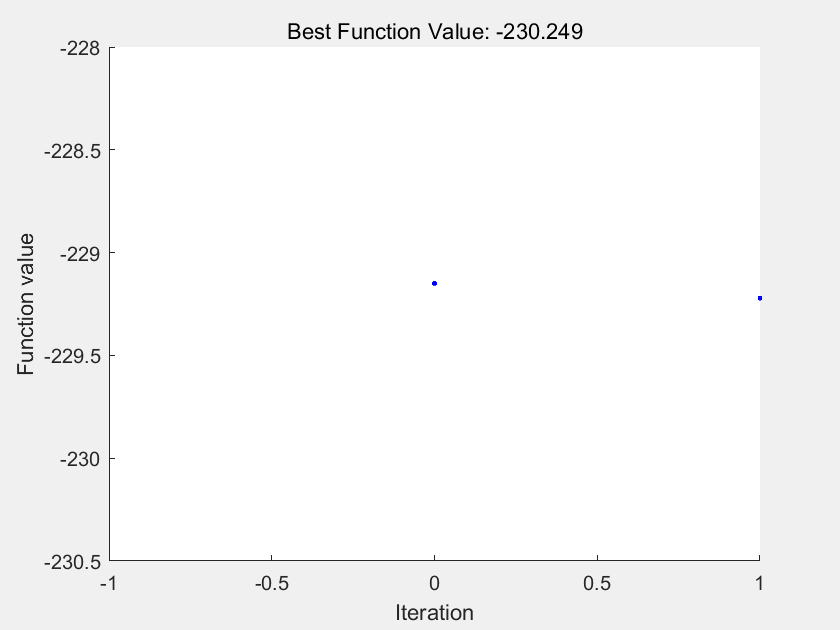

Switching to the hybrid optimization algorithm (FMINCON).
FMINCON ended.


x = 1.0e+05 *

    1.0000    0.0000


fval = -230.2487

exitflag = 1

output = 包含以下字段的 struct :
      rngstate: [1×1 struct]
    iterations: 69
     funccount: 1512
       message: 'Optimization ended: relative change in the objective value ↵over the last OPTIONS.MaxStallIterations iterations is less than OPTIONS.FunctionTolerance.↵FMINCON: 可能存在局部最小值。满足约束。↵↵fmincon 已停止，因为当前步长小于↵步长容差值并且在约束容差值范围内满足约束。↵↵<停止条件详细信息>↵↵优化已停止，因为 x 的所有元素的相对变化↵小于 options.StepTolerance = 1.000000e-10，↵并且相对最大约束违反值 0.000000e+00 小于 options.ConstraintTolerance = 1.000000e-06。↵'
    hybridflag: 2



narvs = 2;
x_lb = [0,0];
%x_ub = 1; % x的上界
x_ub= [100000,1];
options = optimoptions('particleswarm','MaxIterations',800,'Display','iter','PlotFcn','pswplotbestf','HybridFcn',@fmincon);  
[x,fval,exitflag,output] = particleswarm(@Obj_fun, narvs, x_lb, x_ub,options)   

x(1)

ans = 100000

x(2)

ans = 0.4086

function [W]=Obj_fun(c)
    %initialize parameter
    %k=10000;                                 %比例系数
    g=9.8;                                   %重力加速度 (m/s2)                                 
    %%初值设置               
    v1=0;                                    %浮子的初始速度 (m/s)
    v2=0;                                    %振子的初始速度 (m/s)
    x_f=0;                                   %浮子的初始位移 (m) (以浮子的重心为坐标轴原点)
    x_v=0;                                   %振子的初始位移 (m)
    X0=[x_f;x_v;v1;v2];
    w=2.2143;                                %入射波浪频率 (rad/s)orsay %入射波浪角速度（rad/s）
    T=2*pi/w;
    T_end=floor(80*T);                       %总数值模拟时间(s) 
    tspan=[0,T_end];   
    options = odeset('MaxStep', 0.1);        % 设置最大步长为 0.1
    [t, X] = ode45(@(t,X)S_diff_equ(t,X,c), tspan, X0, options);
    X=X';
    delta_v=abs(X(3,:)-X(4,:));
    k=c(1)*delta_v.^c(2);
    l=length(t);
    W=trapz(t(l-floor(l/10):end),k(l-floor(l/10):end).*delta_v(l-floor(l/10):end).^2)/(t(end)-t(l-floor(l/10)));
    W=-W;
end
function delta_f=ca_f_float(rho,g,x,V0,V_max,r_cost,h) 
    if x<=-h
        delta_V=V0-V_max;
    elseif x<=3-h&&x>-h
        delta_V=-x*h*pi*r_cost^2; 
    elseif x<=3.8-h&&x>3-h
        delta_V=-pi*r_cost^2*(3-h)-1/3*pi*((3.8-x)/0.8)^2*(3.8-x);
    else 
        delta_V=-V0;
    end
    delta_f=rho*g*delta_V;
end
function dxdt=S_diff_equ(t,X,c) 
    %initialize parameter
    m1=4866;                                 %浮子质量 (kg)
    r_f=1;                                   %浮子底半径 (m)
    h_cast=3;                                %浮子圆柱部分高度 (m)
    h_cone=0.8;                              %浮子圆锥部分高度 (m)
    V_cast=pi*r_f^2*h_cast;                  %圆柱体积 (m3)
    V_cone=1/3*h_cone*pi*r_f^2;              %圆锥体积(m3)
    V_max=V_cone+V_cast;                     %浮子体积
    m2=2433;                                 %振子质量 (kg)
    m_add=1165.992;                          %垂荡附加质量 (kg)
    g=9.8;                                   %重力加速度 (m/s2)
    G1=m1*g;                                 %浮子重力  (N)
    G2=m2*g;                                 %振子重力  (N)
    rho=1025;                                %海水的密度 (kg/m3)
    ke=80000;                                %弹簧刚度 (N/m)
    w=2.2143;                                %入射波浪频率 (rad/s)orsay %入射波浪角速度（rad/s）                 
    kr=167.8395;                             %垂荡兴波阻尼系数 (N·s/m)
    f_max=4890;                              %垂荡激励力振幅 (N)
    V0=V_max-(G1+G2-f_max)/(rho*g);          %初始沉入水中体积(m3)
    r_cost=1;                                %浮子底半径 (m)
    h=(V_max-(m1*g+m2*g)/(rho*g))/pi;        %水面的高度(m)
    k=c(1)*(abs((X(3)-X(4))).^c(2));
    dxdt=zeros(4,1);
    dxdt(1)=X(3);
    dxdt(2)=X(4);
    dxdt(3)=(-k*(X(3)-X(4))-ke*(X(1)-X(2))+f_max*cos(w*t)-kr*X(3)+ca_f_float(rho,g,X(1),V0,V_max,r_cost,h))/(m1+m_add);
    dxdt(4)=(k*(X(3)-X(4))+ke*(X(1)-X(2)))/m2;
    
end
